# Interoperability with TensorFlow and PyTorch

Create by Fred Liu  2022/10/25

Reference Scoure: [**Sivylla Paraskevopoulou**](https://www.mathworks.com/matlabcentral/profile/authors/16845908?s_tid=blg_to_profile),  

[https://blogs.mathworks.com/deep-learning/2022/10/04/whats-new-in-interoperability-with-tensorflow-and-pytorch/](https://blogs.mathworks.com/deep-learning/2022/10/04/whats-new-in-interoperability-with-tensorflow-and-pytorch/)

Reference scoure: MATLAB Doc

## Tips on Importing Models from TensorFlow, PyTorch, and ONNX

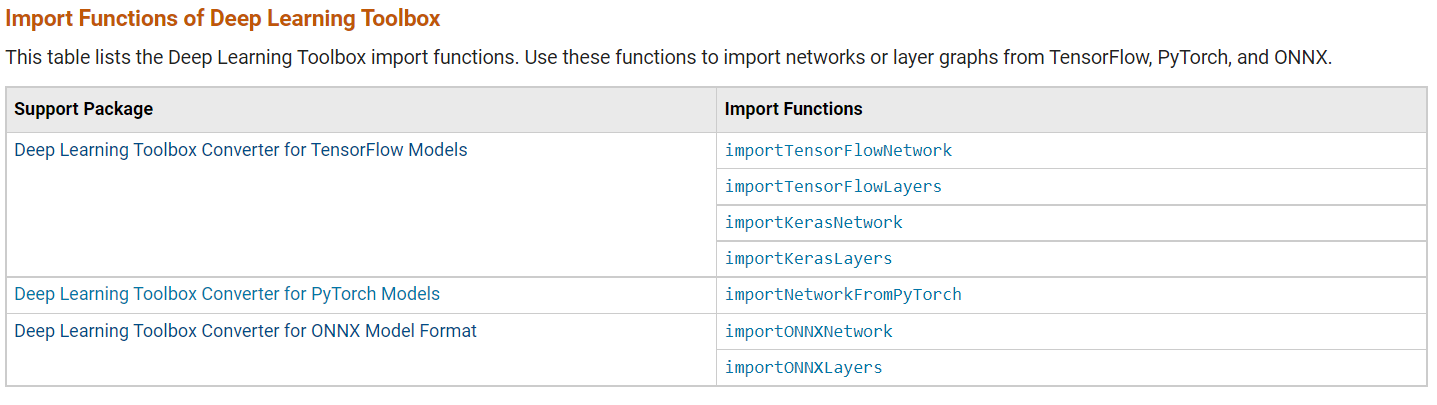

The Deep Learning Toolbox Converter for TensorFlow Models support package offers these functions:

- `importTensorFlowNetwork` and `importKerasNetwork` — Import a TensorFlow model as a network.

- `importTensorFlowLayers` and `importKerasLayers` — Import a TensorFlow model as a layer graph.

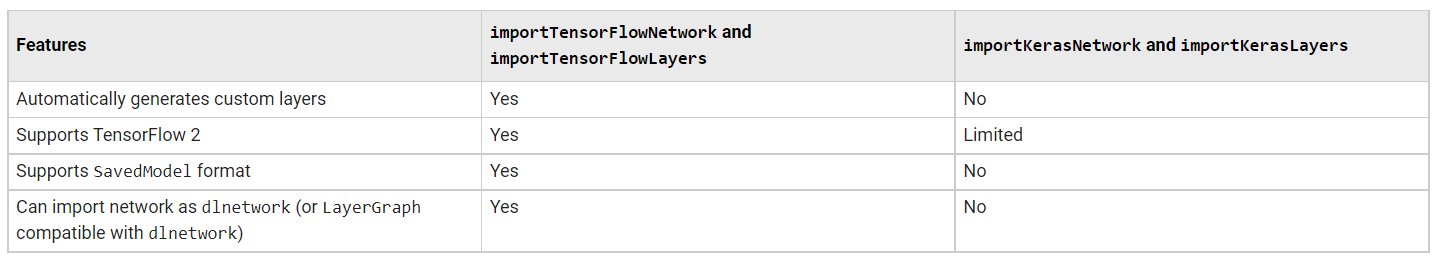

## Export to TensorFlow

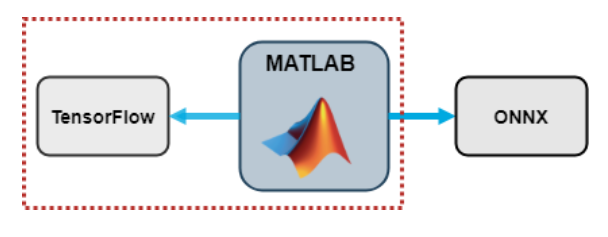

Support Package: [Deep Learning Toolbox Converter for TensorFlow Models](https://www.mathworks.com/matlabcentral/fileexchange/64649-deep-learning-toolbox-converter-for-tensorflow-models)

Function: exportNetworkToTensorFlow:

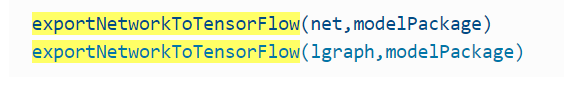

- You can export deep learning networks and layer graphs (e.g., convolutional, LSTM) directly to TensorFlow.

- It’s easy to export a network, load it as a TensorFlow model, and use the exported model for prediction. For a relevant example, see [Export Network to TensorFlow and Classify Image](https://www.mathworks.com/help/deeplearning/ref/exportnetworktotensorflow.html#mw_b88d248d-a405-4cfa-a1c3-f610dfc41675).

- It’s easy to export an untrained layer graph, load it as a TensorFlow model, and train the exported model. For a relevant example, see [Export Untrained Layer Graph to TensorFlow](https://www.mathworks.com/help/deeplearning/ref/exportnetworktotensorflow.html#mw_969bbaaf-2bad-47fd-bba4-e62ff2bb79d3).

- You can save the exported model in any standard TensorFlow format, such as SavedModel or HDF5 format, and share it with your colleagues who work in TensorFlow.

- Many MATLAB layers can be converted to TensorFlow layers. For a full list of the layers, see [Layers Supported for Export to TensorFlow](https://www.mathworks.com/help/deeplearning/ref/exportnetworktotensorflow.html#mw_5df2ceb2-14b1-4133-9a27-3542d9a517de).

net = darknet19;
exportNetworkToTensorFlow(net,'DarkNet19')


The DarkNet19 package contains four files:

- The _init_.py file, which defines the DarkNet19 folder as a regular Python package.

- The model.py file, which contains the code that defines the untrained TensorFlow-Keras model.

- The README.txt file, which provides instructions on how to load the TensorFlow model and save it in HDF5 or SavedModel format.

- The weights.h5 file which contains the model weights in HDF5 format.

% using python code: MLtoTensorFlow.ipynb


## Import TensorFlow 2

[`net`](https://www.mathworks.com/help/deeplearning/ref/importtensorflownetwork.html#mw_89bde25b-204a-412a-92eb-fee99bcaf802) `= importTensorFlowNetwork(`[`modelFolder`](https://www.mathworks.com/help/deeplearning/ref/importtensorflownetwork.html#mw_f9337226-5b84-4ed6-ae7a-709053a24c5d_sep_mw_d56328f2-46c8-4f24-a1b2-65c43cb8a972)`)` imports a pretrained TensorFlow™ network from the folder `modelFolder`, which contains the model in the saved model format (compatible only with TensorFlow 2). The function can import TensorFlow networks created with the TensorFlow-Keras sequential or functional API. `importTensorFlowNetwork` imports the layers defined in the `saved_model.pb` file and the learned weights contained in the `variables` subfolder, and returns the network `net` as a `DAGNetwork` or `dlnetwork` object.

`importTensorFlowNetwork` requires the Deep Learning Toolbox™ Converter for TensorFlow Models support package. If this support package is not installed, then `importTensorFlowNetwork` provides a download link.

modelFolder = 'DarkNet19_savedmodel';
TFnet = importTensorFlowNetwork(modelFolder,'TargetNetwork','dlnetwork')


## Import KerasNetwork

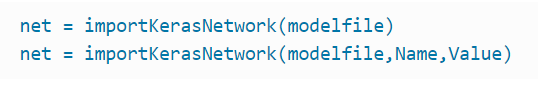

modelfileKeras = 'digitsDAGnet.h5';
Kerasnet = importKerasNetwork(modelfileKeras)

Importing the saved model...


Translating the model, this may take a few minutes...
Finished translation. Assembling network...
Import finished.


TFnet =   dlnetwork with properties:

         Layers: [65×1 nnet.cnn.layer.Layer]
    Connections: [64×2 table]
     Learnables: [74×3 table]
          State: [36×3 table]
     InputNames: {'input_unnormalized'}
    OutputNames: {'flatten_4'}
    Initialized: 1

  View summary with summary.


## Import from PyTorch

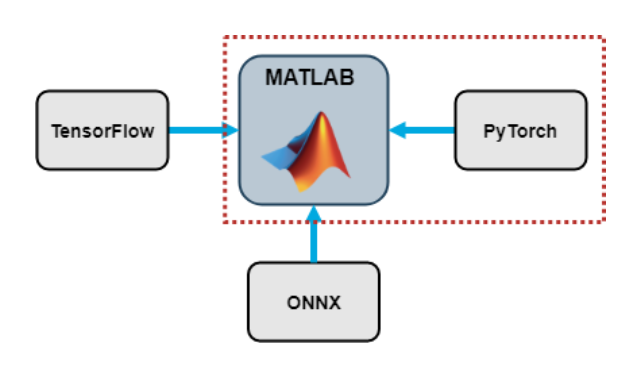

Support Package: [Deep Learning Toolbox Converter for PyTorch Models](https://www.mathworks.com/matlabcentral/fileexchange/111925-deep-learning-toolbox-converter-for-pytorch-models)

Function: importNetworkFromPyTorch:

% using python code: PyTorchtoML.ipynb

Import the PyTorch model into MATLAB by using the `importNetworkTFromPyTorch` function. The function imports the model as an uninitialized `dlnetwork` object without an input layer.

net = importNetworkFromPyTorch("traced_mnasnet1_0.pt");

Specify the input size of the imported network and create an image input layer. Then, add the image input layer to the imported network and initialize the network by using the [`addInputLayer`](https://www.mathworks.com/help/deeplearning/ref/dlnetwork.addinputlayer.html) function (also new in R2022b).

InputSize = [224,224,3];

net =   DAGNetwork with properties:

         Layers: [13×1 nnet.cnn.layer.Layer]
    Connections: [13×2 table]
     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_activation_1'}


InputLayer = imageInputLayer(InputSize,Normalization="none");
net = addInputLayer(net,InputLayer,Initialize=true);

You might have noticed in the above code that the input dimensions in PyTorch and MATLAB have a different order. For more information, see [Input Dimension Ordering for Deep Learning Platforms](https://www.mathworks.com/help/deeplearning/ug/tips-on-importing-models-from-tensorflow-pytorch-and-onnx.html#mw_ca5d4cba-9c12-4f01-8fe1-6329730c92b2).

For more details on how to import a PyTorch model, how to initialize the imported model, and how to perform workflows (such as prediction and training) on the imported model, see the [Examples](https://www.mathworks.com/help/deeplearning/ref/importnetworkfrompytorch.html#mw_d51e64bc-e9ad-409d-ba4a-d70c47f40449) of the `importNetworkTFromPyTorch` documentation page

## Interoperability Capabilities Summary

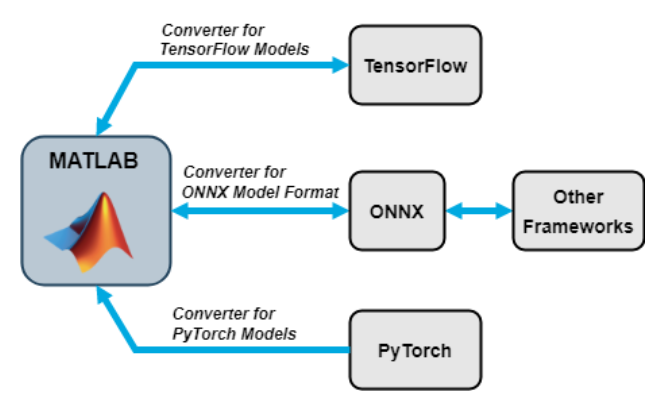

The interoperability support packages allow you to connect Deep Learning Toolbox with TensorFlow, Pytorch, and ONNX. Use the import and export functions to access models available in open-source repositories and collaborate with colleagues who work in other deep learning frameworks.More information:

- To find all the available import and export functions (and their documentation), go to [Deep Learning Import and Export](https://www.mathworks.com/help/deeplearning/deep-learning-import-and-export.html).

- To learn more about how to import and export networks, see [Interoperability Between Deep Learning Toolbox, TensorFlow, PyTorch, and ONNX](https://www.mathworks.com/help/deeplearning/ug/interoperability-between-deep-learning-toolbox-tensorflow-pytorch-and-onnx.html).

- For answers to common questions about importing models, see [Tips on Importing Models from TensorFlow, PyTorch, and ONNX](https://www.mathworks.com/help/deeplearning/ug/tips-on-importing-models-from-tensorflow-pytorch-and-onnx.html).

- If you are working just in MATLAB, you can probably find a suitable network in our constantly-updated­­­­ model repository: [MATLAB Deep Learning Model Hub](https://github.com/matlab-deep-learning/MATLAB-Deep-Learning-Model-Hub).

- Check out our previous blog post [Importing Models from TensorFlow, PyTorch, and ONNX](https://blogs.mathworks.com/deep-learning/2022/03/18/importing-models-from-tensorflow-pytorch-and-onnx/); you will find useful tips on importing and an example you can download (focus on importing from TensorFlow).